# This real-time script provides a intuition way to show how to use the PandaSenseKit

## FILE SPEC DEFINITION

The first step to use PandaSenseKit is telling it the name rule of data files.

This part is in process ...

## LOAD DATA

**filename** - the filename should conform to a given format defined by users

clear
[expConfig,csiMatrix,csiMatrixInfo] = readDatFile('./TestSample/U1_G1_N10_L_L1_D0_20200408_1.dat');

**expConfig** - the experiment setting extracted from the filename

expConfig

expConfig = 包含以下字段的 struct :
         user: 1
      gesture: 1
       number: 10
    intensity: 'L'
          loc: 1
          dir: 0
         date: 20200408


**csiMatrix** - a struct array of csi data which has been filled with default values

csiMatrix(1)

ans = 包含以下字段的 struct :
    timestamp_low: 1.8827e+09
       bfee_count: 25625
              Nrx: 3
              Ntx: 3
           rssi_a: 22
           rssi_b: 38
           rssi_c: 34
            noise: -127
              agc: 47
             perm: [2 3 1]
             rate: 275
              csi: [3×3×30 double]
          MAC_Des: '00:16:EA:12:34:56'
          MAC_Src: '00:16:EA:12:34:56'
         Payloads: '654321'


**csiMatrixInfo** - a struct provides an overview of **csiMatrix**

- **csiMatrixInfo.timestamp_low** - estimation about the sampling rate

- **csiMatrixInfo.bfee_count** - showing the missing records

- **csiMatrixInfo.Nrx** - the number of available receiving antennas

- **csiMatrixInfo.Ntx** - the number of available transmitting antennas

- **csiMatrixInfo.MAC_Des** - the MAC address list of transmitters

- **csiMatrixInfo.MAC_Src** - the MAC address list of receivers

- **csiMatrixInfo.Payloads** - the payloads sent by transmitters

csiMatrixInfo

csiMatrixInfo = 包含以下字段的 struct :
    timestamp_low: [1.8827e+09 1.9597e+09 992.2043]
       bfee_count: [25625 36513]
              Nrx: 3
              Ntx: 3
          MAC_Des: {'00:00:00:00:00:00'  '00:16:EA:12:34:56'}
          MAC_Src: {'00:00:00:00:00:00'  '00:16:EA:12:34:56'}
         Payloads: {'000000'  '654321'}


The raw csi data has redundant data for ceitain sensing tasks. For CSI-based sensing tasks, rssi is seldom used. 

So we extract the necessary elems from the csiMatrix before starting the main process of sensing.

**Extrating elements w.r.t. csiMatrixInfo**

% csi = getElemFromCsiMatrix(csiMatrix,csiMatrixInfo,...
%     'timestamp_low', [1.8828e+09 1.9596e+09], ...
%     'bfee_count', [25625 36513], ...
%     'Nrx', [1 3], ...
%     'Ntx', [2 3], ...
%     'MAC_Des', '00:16:EA:12:34:56', ...
%     'MAC_Src', '00:16:EA:12:34:56', ...
%     'Payloads','654321', ...
%     'signal','csi');
csi = getElemFromCsiMatrix(csiMatrix,csiMatrixInfo,...
    'Nrx', [1:3], ...
    'Ntx', [1], ...
    'MAC_Des', '00:16:EA:12:34:56', ...
    'MAC_Src', '00:16:EA:12:34:56', ...
    'Payloads','654321', ...
    'signal','csi');

We get a matrix of csi records where the first two column are timestamp_low and bfee_count used for checking if there were missing records.

Then, the followed Ntx*Nrx*30 columns are complex csi values.

The last up to 4 columns are rssi and noise values.

## PREPROCESSING

Now we start the main process. Since the wireless signal is very noisy due to the influence of the environment and the imperfection design of the hardware. It needs noise reduction and measurement calibration at first.

The codes below shows a full version of calling preprocess() of which the parameters can be customized. In addition, since the parameters are the default values, it can be written as csiPreprocess = preprocess(csi).

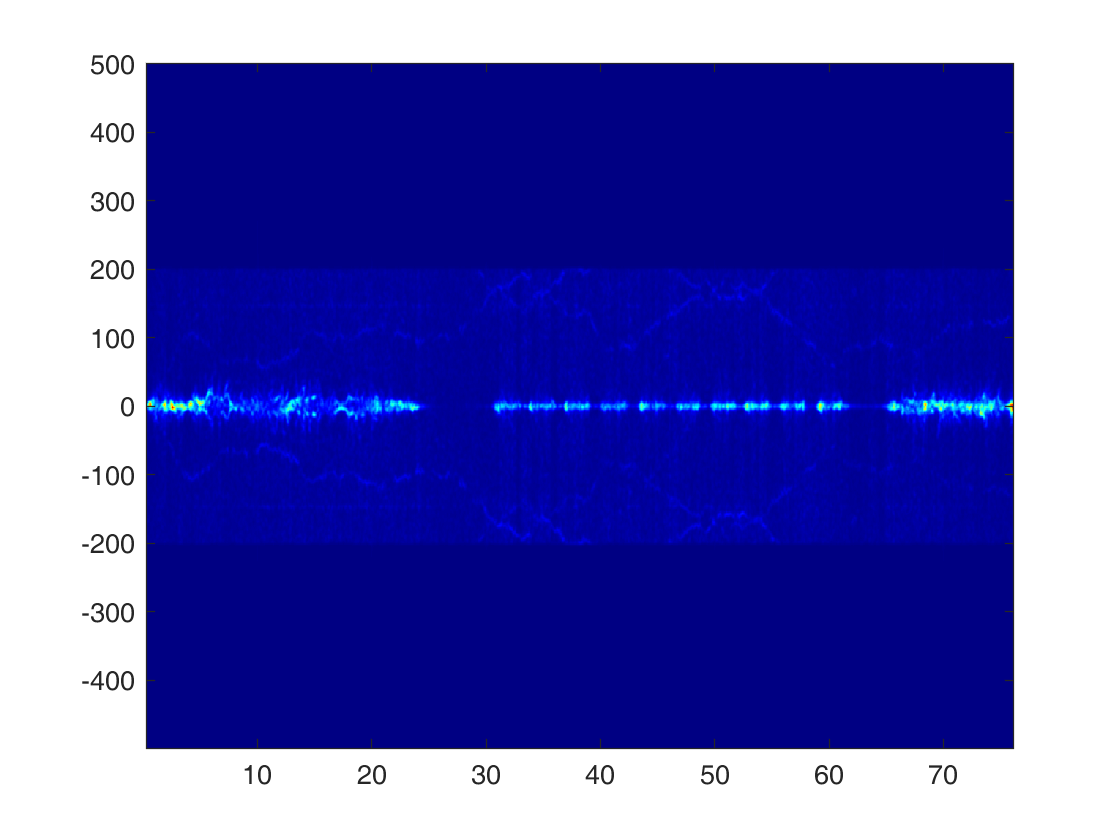

% processData = preprocess(csi, ...
%     'suite', 'InFit', ...
%     'fs', 1000, ...
%     'filter', 'bpf', ...
%     'fc', [2,200], ...
%     'pca', [1000,2:15], ...
%     'stft', [512,16,5], ...
%     'phaseCalibration', 'conjuMulti', ...
%     'device', 'iwl5300');
processData = preprocess(csi, ...
    'suite', 'widance', ...
    'fc', [1,200], ...
    'fs', 1000, ...
    'pca', [10000,2:10], ...
    'stft', [512,16,5]);
hndl = imagesc(processData.time,processData.frequency,processData.psd);
hndl.Parent.YDir = 'normal'; colormap Jet;

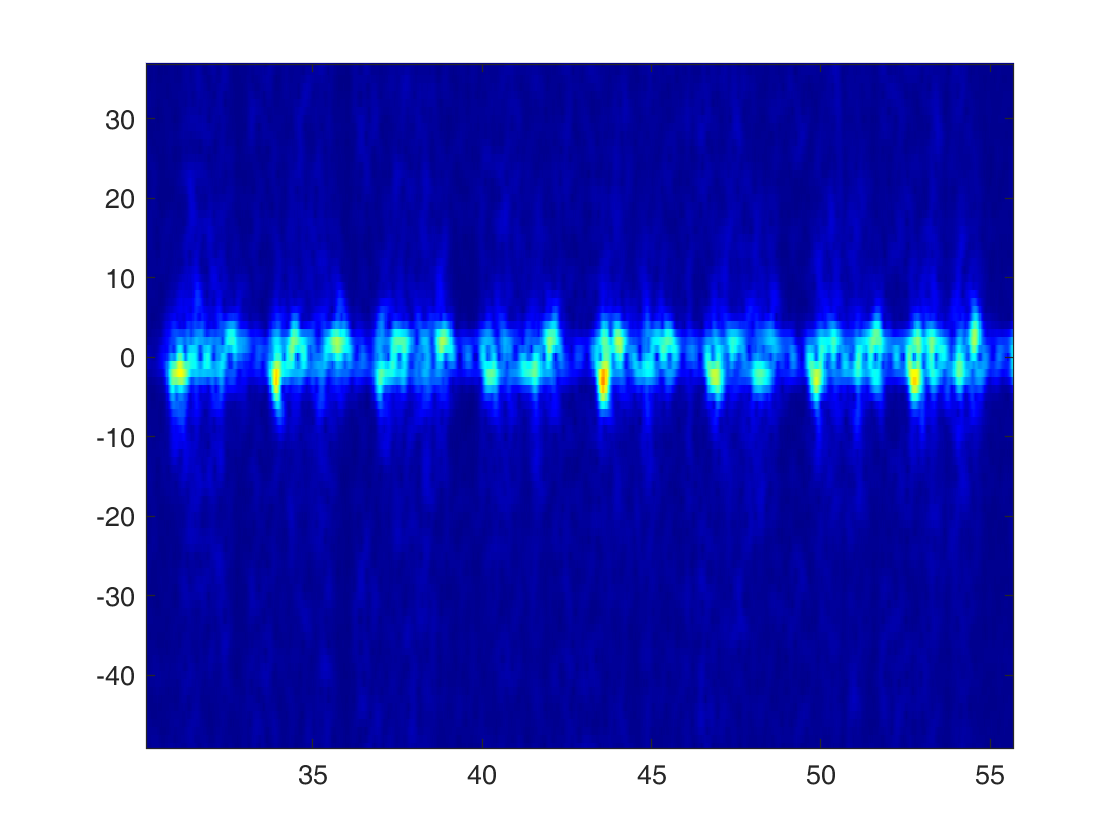

[data,frequency,time] = Preprocessing_WiDance(csi(:,3:end)',1000,[1 200],512,496,2:10,true);
% [data,~,frequency,time] = Preprocessing_CARM(csi(:,3:end)',2:10,1000,512,496);
hndl = imagesc(time,frequency,data);
hndl.Parent.YDir = 'normal'; colormap Jet;